# JHU bootcamp 2019: Ahrens lab -- Analysis of whole-brain neural dynamics 

## 1. Course overview

This course aims to provide an understanding of how to analyze large-scale neural activity in behaving animals. In this experiment, zebrafish adapt their swimming patterns while the visual stimuli move forward, backward and stop. We recorded neural activity across the entire brain at single-cell resolution during this behavior.

**Figure 1: Zebrafish's swimming behavior and neural activity. Movie is available from this **[**link**](https://github.com/ahrens-lab/JHU_Bootcamp/blob/master/activity_movie.mov)

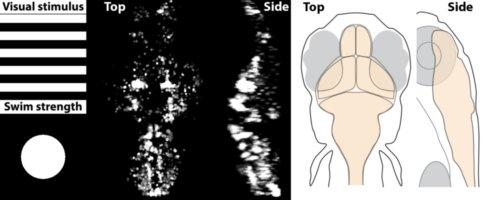

## 2. Goals

In this course, we aim to understand

**(1) basic data handling and plotting skills in Matlab**

**(2) visualization of 3-dimensional data**

**(3) correlation between neural activity and behavioral variables**

**(4) low-dimensionality reduction of large-scale activity data**

## **3. Format**

We do (i) mini lectures/discussions (ii) coding exercise and (iii) Q&A for each sections.   

## **4. Tutors**

Ziqiang Wei (postdoc, Ahrens lab @Janelia)

Jing Xuan Lim (grad student, Ahrens lab @Janelia)

# Section 1: Load and plot data

## Download the data

Please download the data from this [link](https://www.dropbox.com/sh/n6f2y69s3l985bp/AADXv21TYRkZJI5U2AnAbFP5a?dl=0) to your computer.

## **Behavioral data structure**

"swim_power"                     -> Swimming power of fish

"visual_forward"                  -> Forward movement of visual stimuli

"visual_backward"              -> Backward movement of visual stimuli

## Neural data structure

"neural_response_matrix"  -> 2D matrix(neuron number, time)

"neural_position_XYZ"       -> 2D matrix(neuron number, location of cell)

"Volume"                            -> Averaged 3D volume 

## Colormap

"blue_red"                          -> Colormap which change like blue-white-red

## Load data


clear variables; close all; %% clear all variables & close all windows
set(groot,'defaultfigureposition',[0 0 900 300]) % setting default figure size

root_dir='/XXXX/XXXX/XXXX/';

load([root_dir,'behavioral_variables.mat']);
load([root_dir,'selected_neural_data.mat']);
load([root_dir,'colortable.mat']);

% Getting the dimension of the volume
dim=size(Volume);  

% Getting the number of cells
cellnum=size(neural_response_matrix,1);

% Getting the number of timepoints
T_max=size(neural_response_matrix,2);


## Plot behavioral variables (Exercise)

% Plot swim power
figure(1);

subplot(3,1,1);
plot(swim_power);xlabel('time (s)');title('Swim')

% Plot forward visual stimuli (Exercise)



% Plot backward visual stimuli (Exercise)




## Plot neural activity  (Exercise)

figure(2);

subplot(3,1,1);plot(neural_response_matrix(1:10,:)')

% Plot activity of next 10 cells (Exercise)



% Plot activity of all cells (Exercise)



# Section 2: Visualization and indexing of a 3-dimensional volume

## (1) Projections

Multiple ways of projecting a 3D volume to a 2D image?

         - Maximum, Minimum, Sum, Average....

         - Pros and cons for each method

## (2) Indexing

Two ways of specifing a point in a 3D volume.

        - Linear index (e.g., array(i)) and subscript (e.g., array(x,y,z))

        - Pros anc cons

**Figure 2: linear index and subscript**

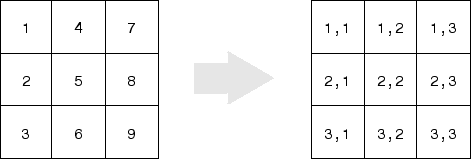

## Plot volume projections from the top and the side (Exercise)

% Top projection view
Volume_XY=sum(Volume,3);

% Side projection view (Exercise)


% Show top view
figure(3);
subplot(1,2,1);imagesc(Volume_XY);
title('XY')
colormap('gray')  

% Show side view (Exercise)




## Plot cell location from the top and the side (Exercise)

% plot location of cell #1 using linear index 

cell_map1=zeros(dim(1),dim(2),dim(3));

cell_map1(neural_position_XYZ(1,:))=1;

% Top projection view
cell_map1_XY=sum(cell_map1,3);

% Side projection view (Exercise)


% Show top view
figure(4);
subplot(1,4,1);imagesc(cell_map1_XY);
title('XY')
colormap('gray')  

% Show side view (Exercise)
subplot(1,4,2);


% plot locations of all cells using linear index into panel 3 and 4 (Exercise)
% use loop over neurons




% Top projection view (Exercise)



% Side projection view  (Exercise)


% Show top view (Exercise)
subplot(1,4,3);


% Show side view (Exercise)
subplot(1,4,4);



# Section 3: Correlation with behavioral variables

## (1) Pearson's correlation coefficient *ρ* 


$$\rho_{X,Y} =\frac{\mathrm{Cov}\left(X,Y\right)}{\sigma_X \sigma_Y }=\frac{E\left\lbrack \left(X-\mu_X \right)\left(Y-\mu_Y \right)\right\rbrack }{\sigma_X \sigma_Y }\text{ }$$


- Cov is covariance, E is expectation

- $\mu_X$, $\mu_Y$ is the mean of *X*, *Y*

- $\sigma_X$, $\sigma_Y$ is the standard deviation of *X*, *Y*

## **(2) Multiple linear regression**


$$Y=\beta_0 +\beta_1 X_1 +\beta_2 X_2 +\beta_3 X_3 +\ldotp \ldotp \ldotp \ldotp$$


- $X_1$, $X_2$, ... are different variables

- $\beta_0$ is constant (intercept)

- $\beta_1$, $\beta_2$,.... are regression coefficients

## (3) Pairwise correlation v.s. multiple regression

        - Difference between the two

        - Meaning of Z-scoring

        - Pros anc cons

## 3.1 Z-score behavioral variables

% Z-score the swim power
swim_power_norm=(swim_power-mean(swim_power))/std(swim_power);


% Z-score the forward stimuli (Exercise)
visual_forward_norm=


% Z-score the backward stimuli (Exercise)
visual_backward_norm=



## 3.2 Z-score neural responses (Exercise)

use loop over neurons

% Z-score the neural response (Exercise)
neural_response_matrix_norm=


## 3.3 Calculate correlations between swim power and neural responses


correlation_neuron_swim = zeros(cellnum,1);

for n=1:cellnum
    coef = corrcoef(neural_response_matrix_norm(n,:),swim_power_norm);
    correlation_neuron_swim(n)=coef(1,2);
end


## 3.4 Calculate correlations between forward/backward visual stimuli (Exercise)

correlation_neuron_forward = zeros(cellnum,1);
correlation_neuron_backward = zeros(cellnum,1);

% Calculate correlations between forward/backward visual stimuli (Exercise)


## 3.5 Create correlation map across the whole brain (Exercise)

% Mimic the code used in "Show Cell locations" above.
% Insert correlation values instead of 1



% Plot correlation coefficient in spatial map (Exercise)

cell_map1=zeros(dim(1),dim(2),dim(3)); 


% Top projection view (Exercise)
cell_map_XY1=

% Side projection view (Exercise)
cell_map_XZ1=

% Show top and side views
figure(5);
set(gcf,'Name','Individual Regression')

subplot(1,6,1);imagesc(cell_map_XY1,[-1 1]);
title('Swim')
subplot(1,6,2);imagesc(squeeze(cell_map_XZ1),[-1 1]);
title('Swim')
colormap(blue_red);colorbar;


%% Show correlation map to forward stimuli  (Exercise)



% Top projection view  (Exercise)



% Side projection view (Exercise)



% Show top and side views (Exercise)

subplot(1,6,3);



subplot(1,6,4);


%% Show correlation map to backward stimuli  (Exercise)




% Top projection view (Exercise)



% Side projection view (Exercise)



% Show top and side views (Exercise)

subplot(1,6,5);



subplot(1,6,6);



## 3.6 Use multivariate regression to neural responses (Exercise)

use regress funciton

% prepare regressor vector, including intercept

regressor=[swim_power_norm; visual_forward_norm; visual_backward_norm; ones(1,1200)]';

% calculate beta for each regressor (Exercise)
betas=zeros(cellnum,4);

for c = 1:cellnum
    
    betas(c,:)=
    
end



% Show spatial regression map to swim power (Exercise)

figure(6);
set(gcf,'Name','Multiple Regression')




% Show spatial regression map to forward stimuli (Exercise)






% Show spatial regression map to backward stimuli (Exercise)









# Section 4: Dimensionarity reduction

## (1) What is dimensionality reduction? Why necessary?

        - Difficulty of large-scale dataset

        - Difference from regression analysis

## (2) PCA v.s. NMF

        - Difference

        - Pros anc cons

        - What's suited for calcium imaging?

**Figure 3: PCA v.s. NMF of facial images**

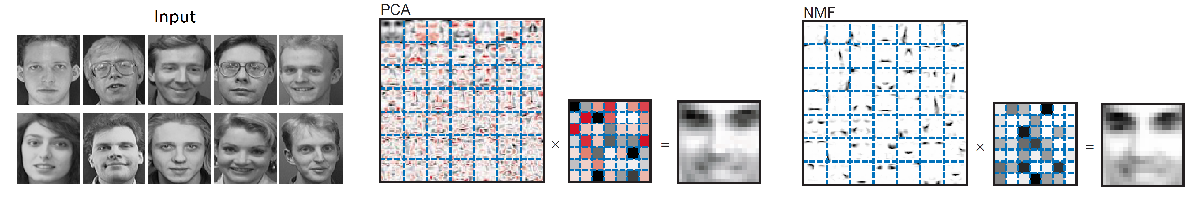

## Principal Component Analysis (PCA) and show maps for each component (Exercise)

[coeff1,comp1]=pca(neural_response_matrix_norm','NumComponents',3); % 3 PCA components

figure(7);
set(gcf,'name','Principal Component Analysis')
for i=1:3
    
    %% plot PCA coefficient into spatial maps (exercise)
    

    
    
    
    %% show top projection (exercise)
    subplot('Position',[0.01 1.00-0.32*i 0.15 0.25]);

    
    
    
    %% show side projection (exercise)
    subplot('Position',[0.17 1.00-0.32*i 0.075 0.25])
    
    
    
    
    
    %% plot principal component (exercise)
    subplot('Position',[0.3 1.00-0.32*i 0.68 0.25])
    
    
    
end

## Non-Negative Matrix Factorization (NNMF) and show maps for each component

rng(3,'twister') %% initialize to a specific seed
[comp2,coeff2]=nnmf(neural_response_matrix_norm',3);

figure(8);
set(gcf,'name','Non-negative matrix factorization')
for i=1:3
    
    %% plot NMF coefficient into spatial maps (exercise)
    

    
    %% top projection (exercise)
    subplot('Position',[0.01 1.00-0.32*i 0.15 0.25]);
    

    
    %% side projection (exercise)
    subplot('Position',[0.17 1.00-0.32*i 0.075 0.25])
    
    
    
    
    %% plot NMF component (exercise)
    subplot('Position',[0.3 1.00-0.32*i 0.68 0.25])
    
    
    
    
end